##   Campionamento

In questa demo vediamo gli effetti del campionamento su di un segnale di parola.

- Carichiamo un segnale audio campionato a Fc=16kHz

- Scartiamo dei campioni per simulare delle frequenze di campionamento più basse, più precisamente $\frac{f_c }{k}$ con $k\in \left\lbrace 2,3,\ldotp \ldotp \ldotp ,8\right\rbrace$

- Ascoltiamo l'effetto dell'aliasing

- Verifichiamo l'effetto sugli spettri di ampiezza

- Utilizziamo il filtraggio passa-basso per eliminare l'aliasing

#### Inizializzazioni

Cancelliamo tutte le variabili in memoria e chiudiamo eventuali figure

clear variables
close all

#### Caricamento

Qui si carica e si ascolta la traccia audio. Se si vuole registrare una nuova traccia, usare `recordVoice.mlx`

namefile='myvoicerecording16kHz.mat';
load(namefile,'Fc','y','N')
% Periodo di campionamento
Tc = 1/Fc;
% numero di campioni nella traccia
M = length(y);
% intervallo temporale della traccia
t =(0:M-1)*Tc;

% Riproduzione della traccia audio registrata
h=msgbox('Segnale vocale'); 
yp=audioplayer(y,Fc);
play(yp)
waitfor(h);
 

#### Ricampionamento

Il segnale $y$ è stato campionato con frequenza $F_c$. Adesso lo ricampioniamo in modo da simulare una diversa frequenza di campionamento.

Abbiamo che $y\left\lbrack n\right\rbrack =x\left(\frac{n}{F_c }\right)$, dove $x\left(t\right)$ è il segnale tempo-continuo campionato con frequenza $F_c$ mentre $n\in Z$ è l'indice del campione. Sia $N$il numero di campioni di $y$.

Adesso vogliamo un nuovo segnale $y_s \left\lbrack n\right\rbrack =x\left(\frac{n}{F_{\textrm{new}} }\right)=x\left(\frac{n}{F_c }\frac{F_c }{F_{\textrm{new}} }\right)=y\left\lbrack n\cdot \textrm{step}\right\rbrack$ dove $\textrm{step}=\frac{F_c }{F_{\textrm{new}} }$. 

Ora però il valore $y\left\lbrack n\cdot \textrm{step}\right\rbrack$ esiste solo se $n\cdot \textrm{step}$ è intero. Poiché questo non si può garantire in generale, la funzione di campionamento implementa un'opportuna *interpolazione* del segnale $y$. Questo passaggio è indispensabile per **simulare** il campionamento ad una frequenza diversa da $F_c$, ma l'approssimazione generata è trascurabile se la frequenza di campionamento iniziale $F_c$ è sufficentemente alta. Nel caso di segnale vocale, l'approssimazione generata è in effetti accettabile.  

% Usiamo una funzione "in-line" per il campionamento
% sintassi delle funzioni in-line:
% nomeFun = @(arg1, arg2, ... argN) [blocco di codice che calcola l'output]
mysampling=@(y,step) interp1(1:numel(y),y,1:step:numel(y),'cubic');

Adesso ricampioniamo il segnale:

fNew = 4000;

step = (Fc/fNew);
% Calcolo della versione sottocampionata del vettore di ingresso
ys = mysampling(y,step);
% vettore dei tempi corrispondente
ts = mysampling(t,step);

Ascoltiamo il segnale ricampionato. L'aliasing è udibile se la nuova frequenza è sufficientemente bassa. Si sentono dei suoni a frequenza intermedia che non appaiono nel segnale originale. 

h2=msgbox(['Audio con il sottocampionamento a Fc =',num2str(fNew/1e3),' kHz']);
ysp=audioplayer(ys,fNew);
play(ysp);
waitfor(h2);

Tracciamo ora i grafici dei segnali. 

Cominciamo con l'andamento temporale. Ecco tutto il segnale

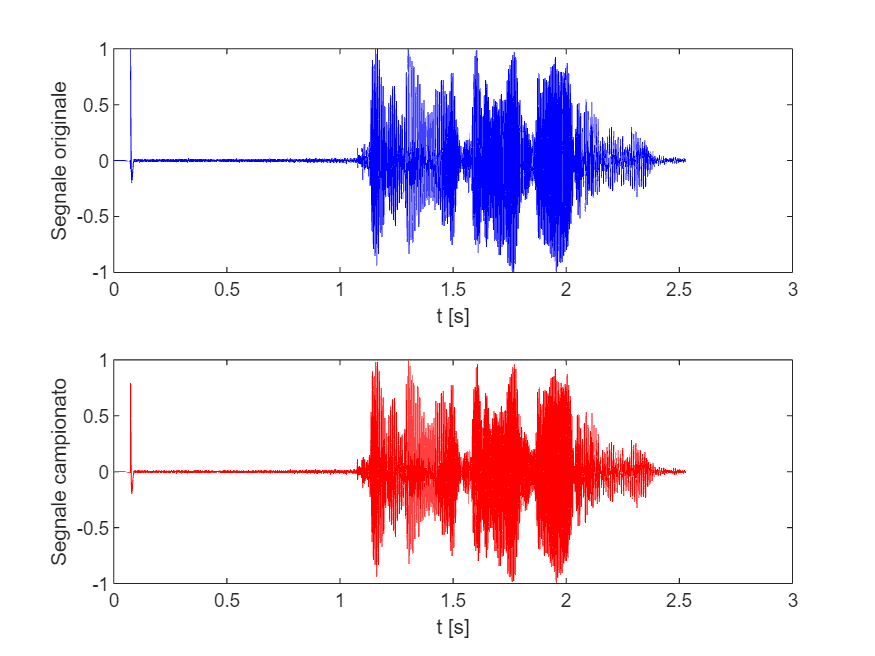

% Grafici
figure
title([' Segnale originale e segnale campionato a F_c=',num2str(fNew/1e3),' KHz'])
subplot(2,1,1)
plot(t,y,'b');
xlabel('t [s]')
ylabel('Segnale originale')
subplot(2,1,2)
plot(ts,ys,'r-');
xlabel('t [s]')
ylabel('Segnale campionato')

Facciamo uno zoom su di un intervallo di 10 ms. Se la nuova frequenza di campionamento è bassa, la perdita di dettaglio diventa visibile. Si noti che qui stiamo solo mostrando il segnale sottocampionato. Matlab traccia dei segmenti di retta tra due campioni (individuati dai cerchietti). Il tipo di interpolazione effettivamente realizzato al momento della riproduzione dipende dalla scheda audio. 

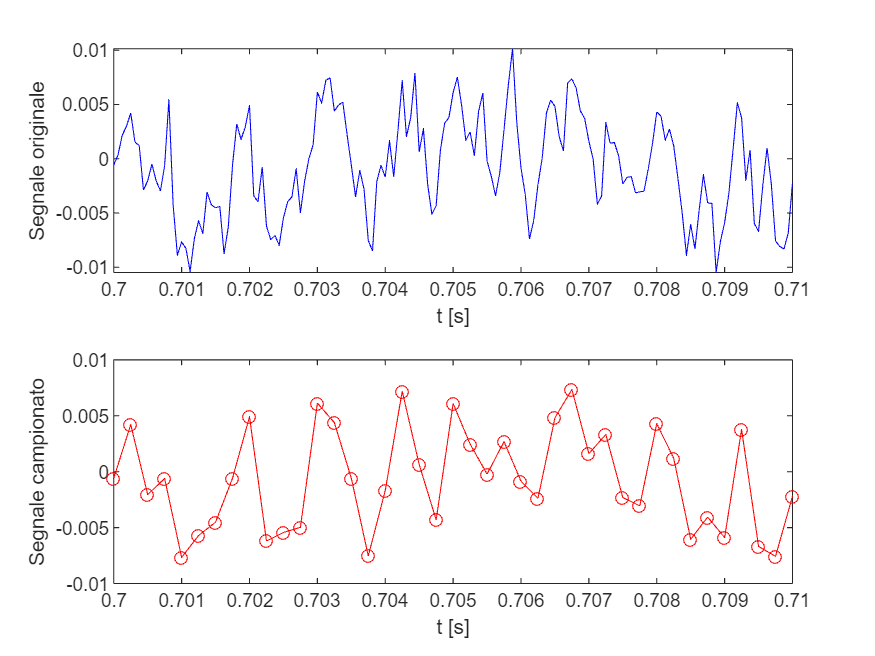

figure
title([' Segnale originale e segnale campionato a F_c=',num2str(fNew/1e3),' KHz'])
subplot(2,1,1)
plot(t,y,'b-');
xlim([0.7,0.71]) %% Qui facciamo lo zoom
xlabel('t [s]')
ylabel('Segnale originale')
subplot(2,1,2)
h=plot(ts,ys,'r-o');
xlim([0.7,0.71]) %% Lo stesso qui
xlabel('t [s]')
ylabel('Segnale campionato')

Ora tracciamo gli spettri d'ampiezza. 

La teoria della trasformata di Fourier (per segnali reali) ci dice che campionando il segnale $x$ a frequenza $f_{\textrm{new}}$,  si ottiene un nuovo segnale il cui spettro è compreso in $\left(0,\frac{f_{\textrm{new}} }{2}\right)$. Tale spettro si ottiene per simmetrizzazione (rispetto a zero) e replica periodica dello spettro di $x$. Se il criterio di Nyquist è rispettato, ciò non comporta aliasing. In caso contrario, appariranno dei nuovi contributi in frequenza dovuti alla replica periodica dello spettro. 

Infatti osserviamo che le basse frequenza del segnale campionato sono distorte: sono presenti dei contributi che provengono dalle frequenze di $x$ superiori a $\frac{f_{\textrm{new}} }{2}$: è l'aliasing

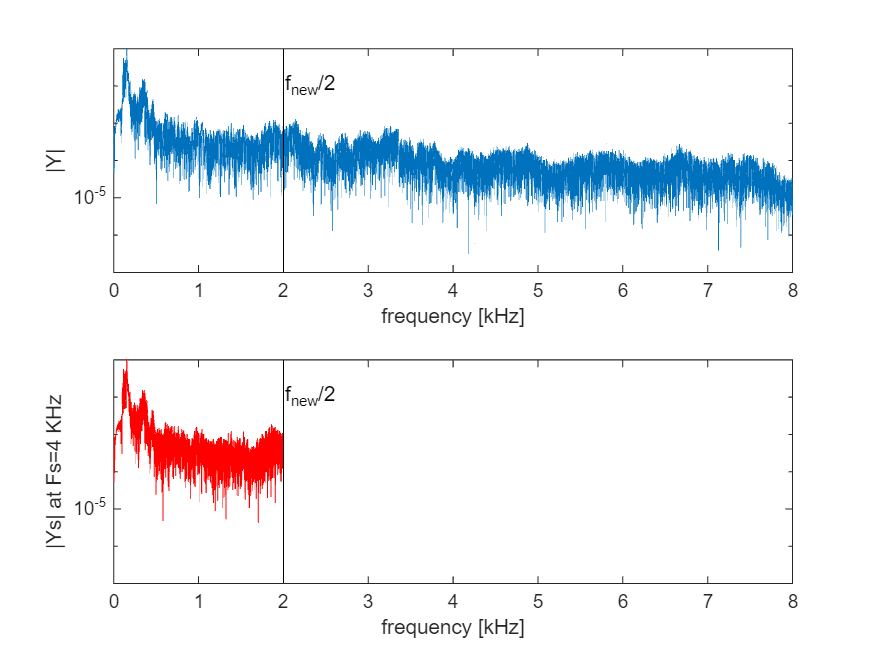

[Y,F ] = CTFT_real(y,Fc);
[YS, FS ] = CTFT_real(ys,fNew);

figure
subplot(2,1,1)
semilogy(F/1e3,Y);  
ylim([1e-7,1e-1]);
line([fNew/2e3 fNew/2e3], [10^-10 1], 'color', 'black');  
text(fNew/2e3,0.01,'f_{new}/2')
xlabel('frequency [kHz]')
ylabel('|Y|')
subplot(2,1,2)
semilogy(FS/1e3,YS,'r');
text(fNew/2e3,0.01,'f_{new}/2');
line([fNew/2e3 fNew/2e3], [10^-10 1], 'color', 'black');  
ylim([1e-7,1e-1]);
ylabel(['|Ys| at Fs=',num2str(fNew/1e3),' KHz'])
xlabel('frequency [kHz]')
xlim([min(F/1e3),max(F/1e3)])

Per vedere meglio questo fenomeno, facciamo uno zoom sulle frequenze tra 0 e 250 Hz

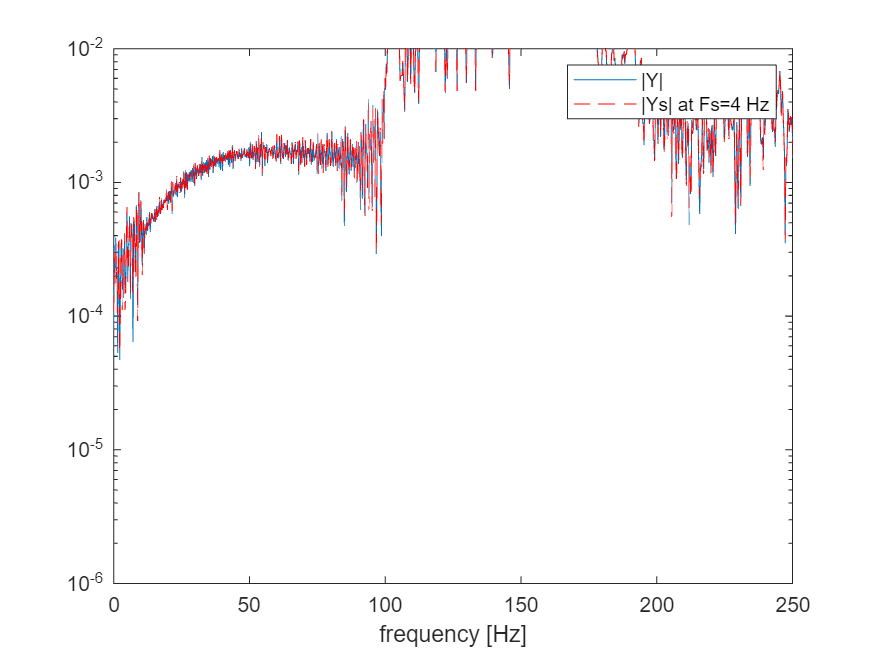

figure;
semilogy(F,Y,FS,YS,'r--');
xlim([0,250])
ylim([1e-6,1e-2])
xlabel('frequency [Hz]')
legend('|Y|',['|Ys| at Fs=',num2str(fNew/1e3),' Hz'])

Si osserva quindi che, non solo il nuovo segnale è forzatamente in un intervallo di frequenze più piccolo, ma che all'interno di queste stesso intervallo ci sono delle frequenze "spurie", cioè l'aliasing. 

Ecco perché, prima di effettuare il sottocampionamento, bisognerebbe prima filtrare il segnale in modo da attenuare il più possibile le frequenze superiori alla frequenza di Nyquist $\frac{f_{\textrm{new}} }{2}$

In Matlab ciò si può fare facilmente.

Progettiamo un filtro con frequenza di taglio  $\frac{f_{\textrm{new}} }{2}$

I dettagli della progettazione di un filtro sono al di là degli obiettivi di questa demo. È sufficiente sapere che è possibile progettare un filtro che riesce ad attenuare grandemente i contributi frequenziali al di là di una certa frequenza (frequenza di taglio), lasciando praticamente immutato il contenuto al di sotto di tale frequenza. 

Fnorm = fNew/Fc; %  frequenza di taglio normalizzata
df = designfilt('lowpassfir','FilterOrder',400,'CutoffFrequency',Fnorm);

'designfilt' requires Signal Processing Toolbox.

D= 200; % 
yLP = filter(df,[y; zeros(D,1)]);
yLP = yLP(D+1:end);                  % Spostamento dei dati per compensare il ritardo

Adesso ascoltiamo l'audio filtrato: si nota l'abbattimento delle alte frequenze, ma non l'introduzione di frequenze spurie. 

h2=msgbox(['Audio filtrato  a Fcut= ',num2str(fNew/1e3/2),' kHz']);
ysp=audioplayer(yLP,Fc);
play(ysp);
waitfor(h2);

Adesso effettuiamo il sottocampionamento su `yLP`

% Calcolo della versione sottocampionata del vettore di ingresso
yLPs = mysampling(yLP,step);
% vettore dei tempi corrispondente
ts = mysampling(t,step);

h2=msgbox('Audio filtrato e sottocampionato');
ysp=audioplayer(yLPs,fNew);
play(ysp);
waitfor(h2);

All'ascolto, i segnali `yLP` e `yLPs` (versione sottocampionata) sono indistinguibili: ciò perché abbiamo effettuato il filtraggio passabasso prima del campionamento. In questo modo, il campionamento in sé non riduce il contenuto d'informazione del segnale. La riduzione è effettuata a monte, con il filtraggio. Nondimeno, questa è la migliore opzione, perché senza il filtraggio avremmo avuto sia la perdita delle alte frequenze, sia l'aliasing. 

Visualizziamo gli spettri di ampiezza, in modo da ritrovare gli effetti del filtraggio e del campionamento. 

Osserviamo che lo spettro di `yLP` è fortemente attenuato al di là della frequenza di taglio (l'asse verticale è in scala logaritmica). Di conseguenza, quando lo spettro viene periodizzato, le alte frequenze riportate in banda base non hanno alcun effetto sensibile. Ciò si verifica osservando che lo spettro di ampiezza del segnale campionato è praticamente indentico a quello del segnale originale - ed anche a quello del segnale filtrato - finché restiamo al di sotto della frequenza di taglio. 

[YLP,F ] = CTFT_real(yLP,Fc);
[YLPS, FS ] = CTFT_real(yLPs,fNew);

figure
subplot(2,1,1)
semilogy(F/1e3,YLP, F/1e3, Y, ':'); hold on
text(fNew/2e3,0.01,'f_{new}/2');
line([fNew/2e3 fNew/2e3], [10^-10 1], 'color', 'black');  xlabel('frequency [kHz]')
ylabel('|Y|')
subplot(2,1,2)
semilogy(FS/1e3,YLPS,'color',"#0072BD");text(fNew/2e3,0.01,'f_{new}/2');
line([fNew/2e3 fNew/2e3], [10^-10 1], 'color', 'black');  
ylim([1e-10,1])
ylabel(['|Ys| at Fs=',num2str(fNew/1e3),' KHz'])
xlabel('frequency [kHz]')
xlim([min(F/1e3),max(F/1e3)])
ylim([1e-10,1])

Verifichiamo che l'aliasing è stato fortemente ridotto (virtualmente eliminato) con lo zoom sulle frequenze tra 0 e 250 Hz

figure;
semilogy(F/1e3,Y,FS/1e3,YLPS,'r--');
xlim([0,0.25])
ylim([1e-7,1])
xlabel('frequency [kHz]')
legend('|Y|',['|YLPs| at Fs=',num2str(fNew/1e3),' KHz'])